# Elaborato trasformata di Fourier discreta

## Analisi della concetrazione di $CO_2$ nell'atmosfera

Analisi della concentrazione di $CO_2$  (biossido di carbonio) nell’atmosfera (in parti per milioni) misurato nell’osservatorio di `Mauna Loa `in **Hawaii**. Partendo da un dataset contenente 216 valori, misurati ogni mese si realizzerà il grafico del fenomeno, il periodogramma ( omettendo la DC component )  della potenza relativo a cicli/mesi (frequenza) e a mesi/ciclo (periodo). 

Determinare i due picchi di massima potenza ed il corrispondente indice e periodo. Ricostruire il fenomeno con la IDFT, ponendo a zero tutti i termini della DFT tranne la DC component e le due componenti relative alla massima potenza, e fare un confronto con quello originale. Ricostruirlo aggiungendo anche  le successive due componenti di potenza maggiore. Cosa si osserva? Come il fenomeno così ricostruito cattura i dati originali? 

Per procedere all'analisi richiesta si dovrà inizialmente caricare il dataset fornito :

clear all
load -ASCII co2.mat

Grafico del fenomeno

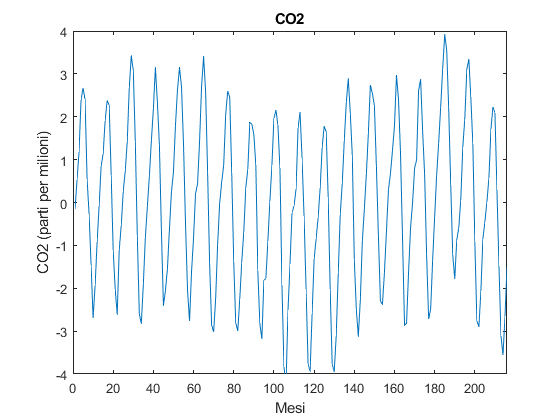

% Frequenza di campionamento, un campione al mese
Fs = 1;
% Numero di campioni 
YLength  = length(co2);

% Estraggo dal dataset t e y per chiarezza, si potrebbe anche evitare.
t  = co2(:,1);
y  = co2(:,2);
figure
plot(t,y), title('CO2'), xlabel('Mesi'), ylabel('CO2 (parti per milioni)'), axis([0 216 -4 4])

Per effettuare il periodogramma della potenza bisogna calcolare la potenza utilizzando la seguente formula : 


$$\frac{{\left|Y\right|}^2 }{N}$$


Dove $Y$ è la trasformata di Fourier discreta `(DFT)` di y :

Y = fft(y);

% Salvo la componente DC e la elimino dall'array Y
DC_component = Y(1);
Y(1) = [];

Il dataset che stiamo utilizzando descrive l'andamento di un segnale reale e pertanto c'è simmetria intorno alla frequenza di `Nyquist`, pertano nel resto dell'elaborazione considereremo solo le frequenze che vanno da quella iniziale a quella di `Nyquist`.

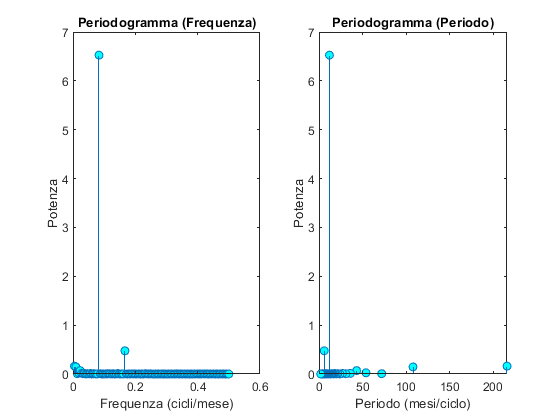

% F
freq = (1:floor(YLength/2))*Fs/YLength;

% periodogramma della potenza
power = (2*abs(Y(1:floor(YLength/2))/YLength)).^2;  
subplot(1,2,1), stem(freq, power,'MarkerFaceColor','c'), 
title('Periodogramma (Frequenza)'), xlabel('Frequenza (cicli/mese)'), ylabel('Potenza');
subplot(1,2,2), stem(1./freq,power,'MarkerFaceColor','c'), 
title('Periodogramma (Periodo)'), xlabel('Periodo (mesi/ciclo)'), ylabel('Potenza');

Si determinano i picchi di massima potenza e le corrispondenti frequenze, periodi ed indici :

[maxPower, maxIndex] = maxk(power, 8);
freqMaxPower = freq(maxIndex);
periodMaxPower = 1./freq(maxIndex);

T = table(maxPower(1:2),freqMaxPower(1:2)', periodMaxPower(1:2)', maxIndex(1:2));
T.Properties.VariableNames = {'Potenza' 'Frequenza' 'Periodo' 'Indici_elementi'}

T = 2×4 table
    Potenza    Frequenza    Periodo    Indici_elementi
    _______    _________    _______    _______________

     6.5265    0.083333       12             18       
    0.47483     0.16667        6             36       


Per ricostruire il fenomeno utilizzando solo la DC component e le due componenti relative alla massima potenza, andremo a costruire un nuovo segnale composto soltanto da queste informazioni:

YF(1:YLength,1) = 0;

% aggiungo la componente DC
YF(1) = DC_component; 

% aggiungo le componenti a massima frequenza e le loro componenti
% simmetriche
YF(maxIndex(1:2)+1) = Y(maxIndex(1:2));

% aggiungo le relative componenti simmetriche che avranno frequenza
% maggiore della frequenza di Nyquist
YF(YLength-maxIndex(1:2)+1) = Y(YLength-maxIndex(1:2));  

Dopodiché, tramite la funzione `ifft`, si effettua l'antitrasformata per tornare al segnale originario opportunamente "pulito":

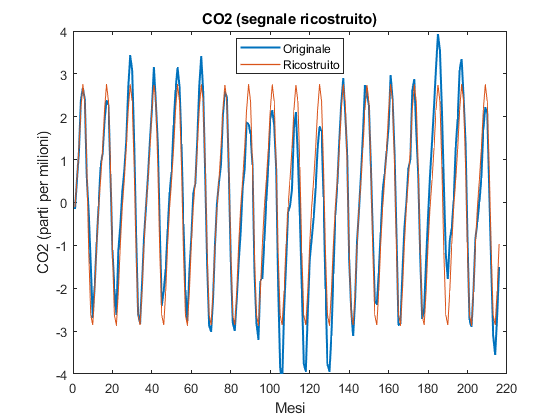

yF = ifft(YF,YLength);
figure
p  = plot(t,y,t,yF); p(1).LineWidth=1.5 ;p(2).LineWidth=1;
title('CO2 (segnale ricostruito)'), xlabel('Mesi'), ylabel('CO2 (parti per milioni)'), axis([0 220 -4 4])
legend('Originale', 'Ricostruito','Location','best')

Da questo primo confronto possiamo osservare che utilizzando solo le due componeti che hanno massima potenza, quello a loro simmetriche e la componente DC possiamo ricostruire un segnale che differisce di poco rispetto all'originale. In particolare l'andamento è pressocchè identico, mentre per l'ampiezze vediamo che per alcune oscillazioni il segnale ricostruito ha ampiezza inferiore, questo è dovuto al fatto che per ricostruire il segnale non ci serviamo di tutte le componenti che abbiamo a disposizione ma ne utilizziamo solo un sottoinsieme di dimensioni nettamente inferiori. Questo però ci fa anche capire che per ricostruire l'andamento del fenomeno o del segnale di partenza non sono necessarie tutte le componenti della DFT.

Procediamo l'analisi aggiungendo ulteriori componenti alla DFT che andremo a trasformare per ricostruire il fenomeno di partenza:

% aggiungo altre due componenti
YF(maxIndex(3:4)+1) = Y(maxIndex(3:4));  
% aggiungo le relative componenti simmetriche
YF(YLength-maxIndex(3:4)+1) = Y(YLength-maxIndex(3:4));

Infine, come in precedenza, tramite `ifft` torniamo al segnale originario:

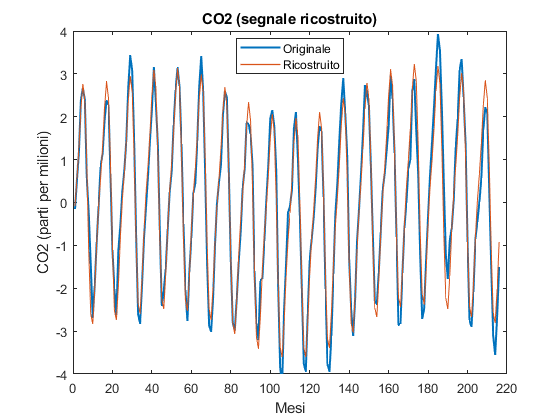

yF2 = ifft(YF,YLength);
figure
p   = plot(t,y,t,yF2);p(1).LineWidth=1.5 ;p(2).LineWidth=1;
title('CO2 (segnale ricostruito)'), xlabel('Mesi'), ylabel('CO2 (parti per milioni)'), axis([0 220 -4 4])
legend('Originale', 'Ricostruito','Location','best')

Come ci aspettavamo, aumentando il numero di componenti il segnale ricostruito si avvicina a quello di partenza, per completezza osserviamo cosa accade se aumentiamo le componenti per ricostruire il segnale :

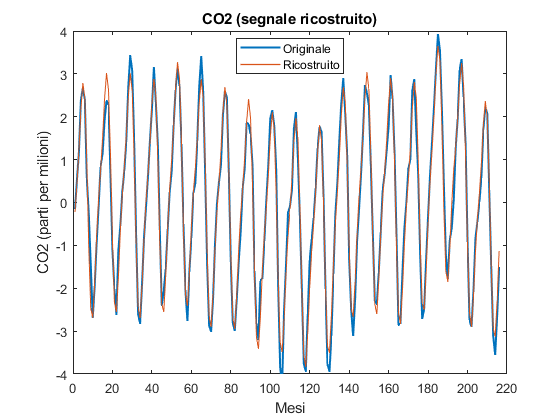

% aggiungo altre due componenti
YF(maxIndex(5:8)+1) = Y(maxIndex(5:8));  
% aggiungo le relative componenti simmetriche
YF(YLength-maxIndex(5:8)+1) = Y(YLength-maxIndex(5:8));

yF3 = ifft(YF,YLength);
figure
p   = plot(t,y,t,yF3);p(1).LineWidth=1.5 ;p(2).LineWidth=1;
title('CO2 (segnale ricostruito)'), xlabel('Mesi'), ylabel('CO2 (parti per milioni)'), axis([0 220 -4 4])
legend('Originale', 'Ricostruito','Location','best')

Si osservi come aumentando ulteriormente le componenti la situazione migliori,ma di poco pertanto possiamo concludere che non tutte le componenti sono necessarie per ricostruire il segnale di partenza e che ne bastano poche decine di componenti ( comprese quelle simmetrice) per ricostruire con buona approssimazione il segnale originale. Questo vale a patto che si possano perdere alcune informazioni sull' ampiezza o che il sengale ricostruito abbia un ampiezza con un errore contenuto in un intervallo ammissibile.

# Segnale musicale

Nel file `vicru.mat` vi è un segnale musicale con frequenza di campionamento Fs=8192Hz in cui è presente un rumore stazionario. Ascoltare il file, analizzare il segnale in frequenza tramite il periodogramma e lo spettrogramma usando la finestra di Blackman con N=512 . Analizzando lo spettrogramma individuare il rumore, eliminarlo, ricomporre il segnale, rifarne il periodogramma e lo spettrogramma ed ascoltarlo. Scrivere infine il brano in un file.wav.

## Soluzione

Inizialmente si è necessario a caricare il file `vicru.mat `che contiene il segnale musicale da cui si vuole rimuovere il rumore che è possibile ascoltare eseguendo il codice di seguito:

clear all
load vicru.mat
Fs = 8192;
soundsc(y);

Successivamente, dopo aver calcolato la DFT, si è effettuata l'analisi del segnale andando a stampare rispettivamente periodogramma e spettrogramma:

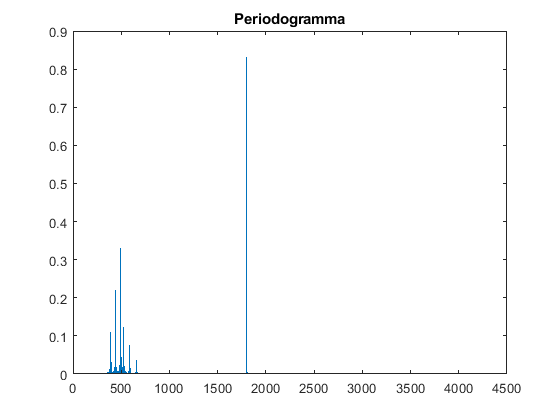

YLength = length(y);
Y = fft(y);
freq = (0:floor(YLength/2))*Fs/YLength;
AMP = 2*abs(Y(1:floor(YLength/2)+1)/YLength);

figure
stem(freq,AMP,'Marker','none'), title('Periodogramma')

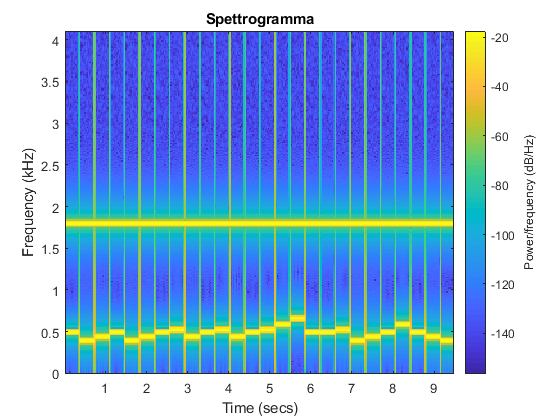

N=512;
spectrogram(y,blackman(N),floor(0.5*N),N,Fs,'yaxis'), title('Spettrogramma')

Sappiamo che il rumore è di tipo stazionario e pertano è possibile individuarlo dallo spettogramma appena generato. In particolare è stato possibile individuare la componente di rumore stazionaria nel range di frequenze  che vanno da `1.5 KHz` a `2 KHz `e non essendoci ulteriori segnali in questo intervallo di frequenze potremmo procedere alla rimozione del rumore direttamente, ma per completezza andiamo a individuare analiticamente le frequenze in cui è presente la componente di rumore. Innanzi tutto vediamo cosa succede tra  `1.5 KHz` a `2 KHz :`

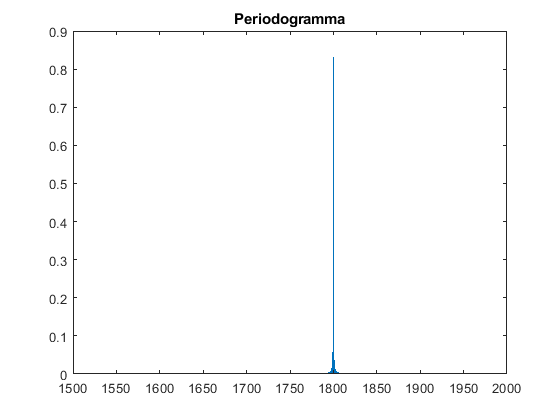

noiseFreq = find((freq>=1500) & (freq<=2000));
stem(freq(noiseFreq),AMP(noiseFreq),'Marker','none'), title('Periodogramma')

Già da questo spettro vediamo che il rumore presenta componenti tra `1.7 KHz` e `2 KHz`, di seguito effettuamo ancora un piccolo zoom per poi eliminare il rumore nel miglior modo possibile:

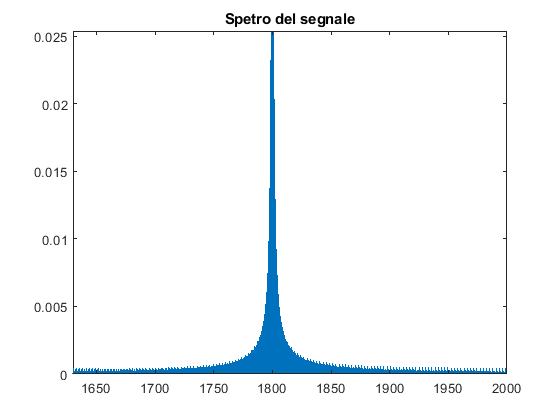

stem(freq(noiseFreq),AMP(noiseFreq),'Marker','none'), title('Spetro del segnale'),xlim([1630 2000])
ylim([0.0000 0.0254])

Procediamo ora a eliminare il rumore presente tra  `1.7 KHz` e `1.9 KHz`

YF = Y;
% cerco gli indici delle componenti alle frequenze del rumore e le elimino
noiseFreq = find((freq>=1700) & (freq<=1900));
YF(noiseFreq) = 0;
YF(YLength+2-noiseFreq) = 0;

yNoNoise = ifft(YF);

Dopo aver eliminato le componenti rumorose e ricostruito il segnale, analizziamo il nuovo periodogramma e spettrogramma:

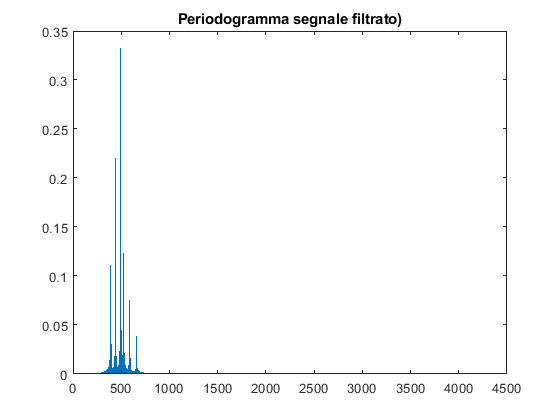

AMPNoNoise = 2*abs(YF(1:floor(YLength/2)+1)/YLength);
stem(freq,AMPNoNoise,'Marker','none'), title('Periodogramma segnale filtrato)')

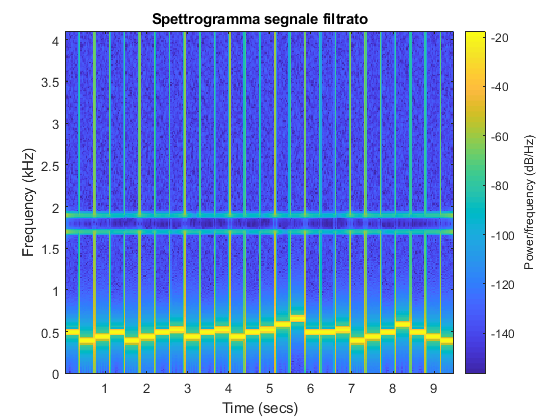

spectrogram(yNoNoise,blackman(N),floor(0.5*N),N,Fs,'yaxis'),title('Spettrogramma segnale filtrato')

Come ci aspettavamo il rumore stazionario, presente nel brano originale, è stato rimosso ed è possibile verificarlo riascoltando il nuovo audio :

soundsc(yNoNoise);

Infine il nuovo brano viene salvato sul disco con l'estensione .wav:

audiowrite('vircu.wav',yNoNoise,Fs);